% Data 
inverter_matrix = [2 -1 -1;
                   -1 2 -1;
                   -1 -1 2];
f = 50;
L = 1.5e-3;
C = 1000e-6;
R = 10;
w = 2*pi*f;
Vr = 220;
Vc = 700;
V = Vr;


wf = 2*pi*f;
Q = 0.25;

## Simulation avec Hystérésis


Im = ((Vc^2)*sqrt(2))/(3*R*Vr)

Im = 104.9946

Vm = ((Vc^2)*2)/(3*R*Im);

% H= 1% Im
% H = Im/100
Fd = 10e3;
Td=1/Fd;
H = Vc/(6*L*Fd)
delta = 0;
eps_on =  H;
eps_off = -H;

S_on = 1;
S_off = 0;
Te = 1e-6;
Fs = 1/Te;
Ts = 0.2;
% len = Ts/Te
% df = -len/2:1:len/2 %


sim("Redresseur_MLI_3Ph_Hysteresis.slx")

ans =   Simulink.SimulationOutput:

                     I1: [1x1 timeseries] 
                 I1_ref: [1x1 timeseries] 
                     I2: [1x1 timeseries] 
                     I3: [1x1 timeseries] 
                    Idc: [1x1 timeseries] 
                     V1: [1x1 timeseries] 
                     Vc: [1x1 timeseries] 
                 Vc_ref: [1x1 timeseries] 
                   tout: [200001x1 double] 
                     u1: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


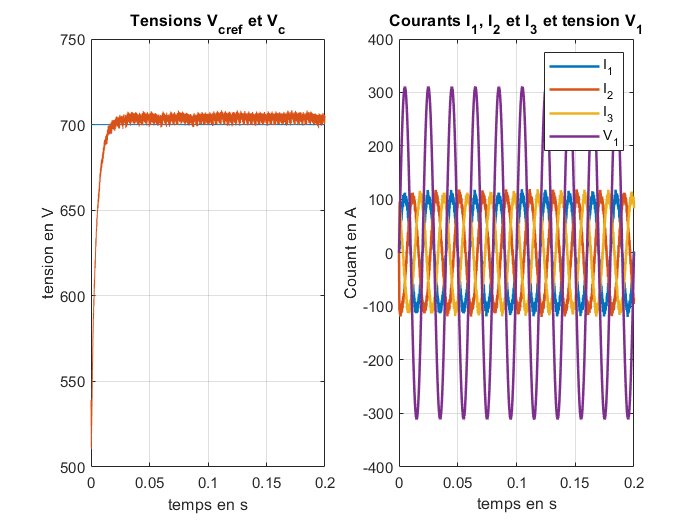



% X =fftshift(fft(ans.u1.Data)); % ramène les valeurs vers le zéro
% X_mag = abs(X/len) % permet de conserver la valeur absolue des rais FFT
% 
% signal = ans.u1.Data;
% % FFT Calculation
% N = length(signal);
% y_fft = fft(signal);
% y_fft = y_fft(1:N/2+1);      % Keep positive frequencies
% 
% % Frequency axis
% f_axis = (0:N/2) * (Fs / N);
% 
% % Amplitude Spectrum
% amplitude_spectrum = abs(y_fft) / N;
% amplitude_spectrum(2:end-1) = 2 * amplitude_spectrum(2:end-1);
% 
% % Plot
% figure;
% plot(f_axis, amplitude_spectrum);
% xlabel('Frequency (Hz)');
% ylabel('Amplitude');
% title('Amplitude Spectrum of the Signal');
% figure(2)
% subplot(2,2,1)
% t = ans.Vc_ref.Time;
% plot(t,ans.u1.Data); grid on
% title("u_1")
% subplot(2,2,2)
% plot(df,X_mag,"lineWidth",1.5); grid on
% title("spectre de u_1");
% xlabel("frenquence en Hz")
% ylabel("Amplitude")
figure
t = ans.Vc_ref.Time;
subplot(1,2,2)
plot(t,ans.I1.Data,t,ans.I2.Data,t,ans.I3.Data,t,ans.V1.Data,'LineWidth',1.5); grid on
title("Courants I_1, I_2 et I_3 et tension V_1")
xlabel("temps en s")
ylabel("Couant en A")
legend("I_1","I_2","I_3","V_1")
subplot(1,2,1)
plot(t,ans.Vc_ref.Data,t,ans.Vc.Data); grid on
title("Tensions V_c_{ref} et V_c", 'LineWidth',1.5)
xlabel("temps en s")
ylabel("tension en V")

## Simulation du modèle abc avec Correcteur PI analogique

Fd = 5e3

Fd = 5000

Ts = 0.1

Ts = 0.1000

Vq_sat = -sqrt(3/2)*Vm

Vq_sat = -381.0512

wd = 2*pi*Fd;
wbp = wd/sqrt(10);

K = L*wbp;
Ti = sqrt(10)/wbp;
Ta = 1/(wbp*sqrt(10));


sim("Redresseur_MLI_3Ph_MLI_antiwindup_sign.slx")

ans =   Simulink.SimulationOutput:

                     I1: [1x1 timeseries] 
                     I2: [1x1 timeseries] 
                     I3: [1x1 timeseries] 
                    Idc: [1x1 timeseries] 
                     V1: [1x1 timeseries] 
                     Vc: [1x1 timeseries] 
                 Vc_ref: [1x1 timeseries] 
                 carier: [1x1 timeseries] 
                   tout: [100001x1 double] 
                     u1: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


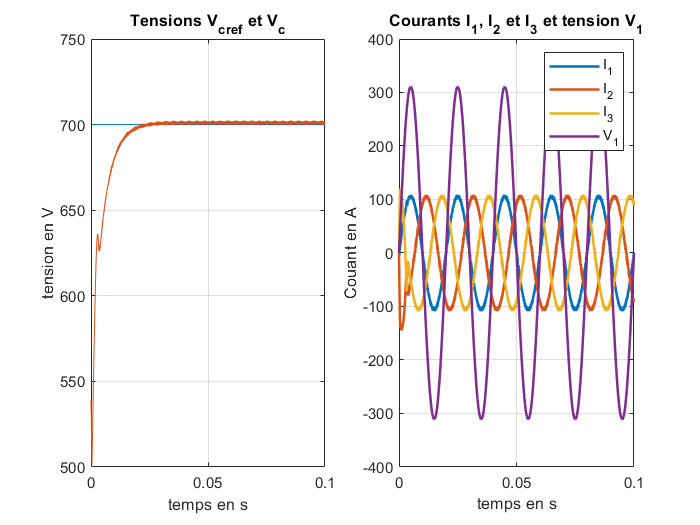


% Te = 1e-6;
% Fs = 1/Te;
% Ts = 0.1;
% len = Ts/Te
% df = -len/2:1:len/2 %
% X =fftshift(fft(ans.u1.Data)); % ramène les valeurs vers le zéro
% X_mag = abs(X/len) % permet de conserver la valeur absolue des rais FFT
% 
% figure(3)
% subplot(2,2,1)
% t = ans.Vc_ref.Time;
% plot(t,ans.u1.Data,t,ans.carier.Data,'LineWidth',1.5); grid on
% title("u_1 et la porteuse");
% legend("u_1","porteuse")
% subplot(2,2,2)
% plot(df,X_mag,"lineWidth",1.5); grid on
% title("spectre de u_1");
% xlabel("frenquence en Hz")
% ylabel("Amplitude")
% subplot(2,2,3)
% plot(t,ans.I1.Data,t,ans.I2.Data,t,ans.I3.Data,t,ans.V1.Data,'LineWidth',1.5); grid on
% title("Courants I_1, I_2 et I_3 et tension V_1")
% xlabel("temps en s")
% ylabel("Couant en A")
% legend("I_1","I_2","I_3","V_1")
% subplot(2,2,4)
% plot(t,ans.Vc_ref.Data,t,ans.Vc.Data); grid on
% title("Tensions V_c_{ref} et V_c", 'LineWidth',1.5)
% xlabel("temps en s")
% ylabel("tension en V")

figure
t = ans.Vc_ref.Time;
subplot(1,2,2)
plot(t,ans.I1.Data,t,ans.I2.Data,t,ans.I3.Data,t,ans.V1.Data,'LineWidth',1.5); grid on
title("Courants I_1, I_2 et I_3 et tension V_1")
xlabel("temps en s")
ylabel("Couant en A")
legend("I_1","I_2","I_3","V_1")
subplot(1,2,1)
plot(t,ans.Vc_ref.Data,t,ans.Vc.Data); grid on
title("Tensions V_c_{ref} et V_c", 'LineWidth',1.5)
xlabel("temps en s")
ylabel("tension en V")

## Simulation du modèle dq avec correcteur PI


Im = ((Vc^2)*sqrt(2))/(3*R*Vr)

Im = 104.9946

Vm = ((Vc^2)*2)/(3*R*Im);


Fd = 5e3;
Td=1/Fd;
Ts = 0.1;
Vq_sat = -sqrt(3/2)*Vm

Vq_sat = -381.0512

wd = 2*pi*Fd;
wbp = wd/10 %sqrt(10);

wbp = 3.1416e+03


K = L*wbp;
Ti = sqrt(10)/wbp;

sim("Redresseur_MLI_3Ph_dq_model.slx");

Te = 1e-6;
Ts = 0.1;
figure(4);
subplot(2,2,1);
t = ans.Vc_ref.Time;
plot(t,ans.Vc_ref.Data,t,ans.Vc.Data); grid on;
title("Tensions V_c_{ref} et V_c",'LineWidth',1.5);
xlabel("temps en s");
ylabel("tension en V");

subplot(2,2,2);
plot(t,ans.Iq.Data,t,ans.Iqref.Data,'LineWidth',1.5); grid on
title("Courant I_q et I_{qref}");
xlabel("temps en s");
ylabel("Couant en A");
legend("I_q","I_{qref}");

subplot(2,2,3);
plot(t,ans.I1.Data,t,ans.I2.Data,t,ans.I3.Data,t,ans.V1.Data,'LineWidth',1.5); grid on
title("Courants I_1, I_2 et I_3 et tension V_1")
xlabel("temps en s")
ylabel("Couant en A")
legend("I_1","I_2","I_3","V_1")

subplot(2,2,4);
plot(t,ans.Id.Data,t,ans.Idref.Data,'LineWidth',1.5); grid on;
title("Courants I_d et I_{dref}");
xlabel("temps en s");
ylabel("Couant en A");
legend("I_d","I_{dref}");

## Simulation du modèle dq avec correcteur RST


Im = ((Vc^2)*sqrt(2))/(3*R*Vr);
Vm = ((Vc^2)*2)/(3*R*Im);


Fd = 10000;
Td=1/Fd;
Ts = 0.05;
Vq_sat = -sqrt(3/2)*Vm

Vq_sat = -381.0512

wd = 2*pi*Fd;
wbp = wd/sqrt(10);

Te = Td

Te = 1.0000e-04

xi = 1; 
wn = wbp;
b1 = Te/L;
p1 = -2*exp(-xi*wn*Te);
p2 = exp(-2*xi*wn*Te);
r0 = (p1+2)/b1

r0 = 25.8865

r1 = (p1-1)/b1

r1 = -19.1135

T = (r0+r1) %4.8 %r0 + r1 % r0+r1

T = 6.7730

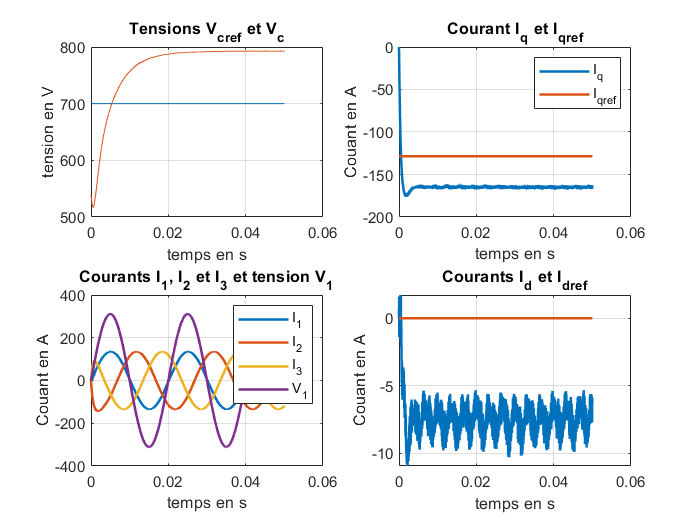

% p1 = -3*exp(-xi*wn*Te);
% p2 = 3*exp(-2*xi*wn*Te);
% p3 = -exp(-3*xi*wn*Te);
% r0 = (p1+3)/b1;
% r1 = (p2-2)/b1
% r2 = (p3+1)/b1
% T = r0 + r2 + r1;
sim("Redresseur_MLI_3Ph_dq_model_RST.slx");

Te = 1e-6;
Ts = 0.1;
figure(4);
subplot(2,2,1);
t = ans.Vc_ref.Time;
plot(t,ans.Vc_ref.Data,t,ans.Vc.Data); grid on;
title("Tensions V_c_{ref} et V_c",'LineWidth',1.5);
xlabel("temps en s");
ylabel("tension en V");

subplot(2,2,2);
plot(t,ans.Iq.Data,t,ans.Iqref.Data,'LineWidth',1.5); grid on
title("Courant I_q et I_{qref}");
xlabel("temps en s");
ylabel("Couant en A");
legend("I_q","I_{qref}");

subplot(2,2,3);
plot(t,ans.I1.Data,t,ans.I2.Data,t,ans.I3.Data,t,ans.V1.Data,'LineWidth',1.5); grid on
title("Courants I_1, I_2 et I_3 et tension V_1")
xlabel("temps en s")
ylabel("Couant en A")
legend("I_1","I_2","I_3","V_1")

subplot(2,2,4);
plot(t,ans.Id.Data,t,ans.Idref.Data,'LineWidth',1.5); grid on;
title("Courants I_d et I_{dref}");
xlabel("temps en s");
ylabel("Couant en A");

%legend("I_d","I_{dref}");

## Boucle de tension : 


Im = ((Vc^2)*sqrt(2))/(3*R*Vr)

Im = 104.9946

Vm = ((Vc^2)*2)/(3*R*Im);

wf = 4*pi*f;
Q = 0.1;
Fd = 10e3;
Td=1/Fd;
Ts = 0.1;
Vq_sat = -sqrt(3/2)*Vm

Vq_sat = -381.0512

wd = 2*pi*Fd;
wbp = wd/sqrt(10)

wbp = 1.9869e+04

w0 = 2*Vq_sat/C

w0 = -7.6210e+05

Wc = 2/(R*C)

Wc = 200

K = L*wbp;
Ti = sqrt(10)/wbp;
wbpt= wbp/10 %5000% Wc % wbp/500

wbpt = 1.9869e+03

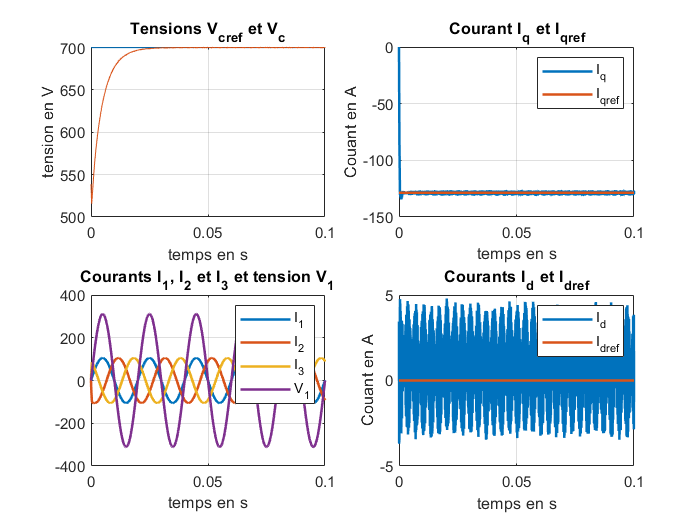


Tit = sqrt(10)/wbpt;
Kt = -(2*C*wbpt)/(sqrt(3/2)*Vm);

sim("Redresseur_MLI_3Ph_dq_model_boucle_de_tension.slx");

Te = 1e-6;
figure(4);
subplot(2,2,1);
t = ans.Vc_ref.Time;
plot(t,ans.Vc_ref.Data,t,ans.Vc.Data); grid on;
title("Tensions V_c_{ref} et V_c",'LineWidth',1.5);
xlabel("temps en s");
ylabel("tension en V");

subplot(2,2,2);
plot(t,ans.Iq.Data,t,ans.Iqref1.Data,'LineWidth',1.5); grid on
title("Courant I_q et I_{qref}");
xlabel("temps en s");
ylabel("Couant en A");
legend("I_q","I_{qref}");

subplot(2,2,3);
plot(t,ans.I1.Data,t,ans.I2.Data,t,ans.I3.Data,t,ans.V1.Data,'LineWidth',1.5); grid on
title("Courants I_1, I_2 et I_3 et tension V_1")
xlabel("temps en s")
%ylabel("Couant en A")
legend("I_1","I_2","I_3","V_1")

subplot(2,2,4);
plot(t,ans.Id.Data,t,ans.Idref.Data,'LineWidth',1.5); grid on;
title("Courants I_d et I_{dref}");
xlabel("temps en s");
ylabel("Couant en A");
legend("I_d","I_{dref}");

## bandwidth influence

figure(5)
num = [Vq_sat*R]
den = [C*R/2 1]
syst = tf(num,den)
bode(syst); grid on



Fd = 10e3;
Td=1/Fd;
Ts = 0.2;
Vq_sat = -sqrt(3/2)*Vm
wd = 2*pi*Fd;
wbp = wd/sqrt(10)
w0 = 2*Vq_sat/C
Wc = 2/(R*C)
K = L*wbp;
Ti = sqrt(10)/wbp;
wbpts = [50 200 wbpt wbp] %5000% Wc % wbp/500
all_t =  {};
all_Vc = {};
all_Vc_ref = {};
all_Iq = {};
all_Iq_ref = {};

for k=1:length(wbpts)
    Tit = sqrt(10)/wbpts(k);
    Kt = -(2*C*wbpts(k))/(sqrt(3/2)*Vm);
    sim("Redresseur_MLI_3Ph_dq_model_boucle_de_tension.slx")
    all_t{k} = ans.Vc.Time;
    all_Vc{k} = ans.Vc.Data;
    all_Vc_ref{k} = ans.Vc_ref.Data;
    all_Iq{k} = ans.Iq.Data;
    all_Iq_ref{k} = ans.Iqref1.Data;
end
figure(6)
subplot(1,2,1)
plot(all_t{1},all_Vc_ref{1}, 'DisplayName', sprintf("V_{cref}"), 'LineWidth',1.5); hold on; 
for k=1:length(wbpts)
    plot(all_t{k},all_Vc{k}, 'DisplayName', sprintf("V_{c} pour W_{bpt}=%.1f rad/s", wbpts(k)), 'LineWidth',1.5); 
end
grid on;
legend('show');
title("Tensions V_c et V_{cref}");
subplot(1,2,2);
plot(all_t{1},all_Iq_ref{1}, 'DisplayName', sprintf("I_{qref}"), 'LineWidth',1.5); hold on; 
for k=1:length(wbpts)
    plot(all_t{k},all_Iq{k}, 'DisplayName', sprintf("I_{q} pour W_{bpt}=%.1f rad/s", wbpts(k)), 'LineWidth',1.5); 
end
grid on;
legend('show');
title("Courants I_q et I_{qref}");


## Developpement de la PLL et impact sur la charge

A = sqrt(3/2)*Vm
Kpll = wbp/A
Tipll = sqrt(10)/wbp
R2 = 50;
Req = (R*R2)/(R+R2)
Fd = 10e3;
Td=1/Fd;
Ts = 0.1;
Vq_sat = -sqrt(3/2)*Vm
wd = 2*pi*Fd;
wbp = wd/sqrt(10)
w0 = 2*Vq_sat/C
Wc = 2/(R*C)
K = L*wbp;
Ti = sqrt(10)/wbp;
Tit = sqrt(10)/wbpt;
Kt = -(2*C*wbpt)/(sqrt(3/2)*Vm);


sim("Redresseur_MLI_3Ph_dq_model_boucle_de_tension_PLL.slx")
% subplot(1,2,1);
% t = ans.Vc_ref.Time;
% plot(t,ans.Vc_ref.Data,t,ans.Vc.Data); grid on;
% title("Tensions V_c_{ref} et V_c",'LineWidth',1.5);
% xlabel("temps en s");
% ylabel("tension en V");
% subplot(1,2,2);
% plot(t,ans.Iq.Data,t,ans.Iqref1.Data,'LineWidth',1.5); grid on
% title("Courant I_q et I_{qref}");
% xlabel("temps en s");
% ylabel("Couant en A");
% legend("I_q","I_{qref}");

subplot(1,2,1);
t = ans.Vc_ref.Time;
plot(t,ans.Vc_ref.Data,t,ans.Vc.Data); grid on;
title("Tensions V_c_{ref} et V_c",'LineWidth',1.5);
xlabel("temps en s");
ylabel("tension en V");

subplot(1,2,2);
plot(t,ans.Ich.Data,'LineWidth',1.5); grid on;
title("Courant I_{ch}");
xlabel("temps en s");
ylabel("Couant en A");
legend("I_{ch}");

subplot(2,2,3);
plot(t,ans.u1.Data,'LineWidth',1.5); grid on
title("rapport cyclique \alpha")
xlabel("temps en s")
%ylabel("Couant en A")
%legend("I_1","I_2","I_3","V_1")

subplot(2,2,4);
plot(t,ans.Iq.Data,t,ans.Iqref1.Data,'LineWidth',1.5); grid on
title("Courant I_q et I_{qref}");
xlabel("temps en s");
ylabel("Couant en A");
legend("I_q","I_{qref}");

